phi=38.1167; %geografische Breite von Palermo
t=0:1:24; %Tageszeiten
H= 15*(t-12); %Stundenwinkel
datum = datetime('2025-01-28'); % Datum der Präsentation
doy = day(datum,'dayofyear');
delta=23.45*sin((2*pi/365)*(doy+284)); % Deklination

sonnenaufgang = fzero(@(t) (sind(phi)*sind(delta)+cosd(phi)*cosd(delta)*cosd(15*(t-12))),[0 12]);
sonnenuntergang = fzero(@(t) (sind(phi)*sind(delta)+cosd(phi)*cosd(delta)*cosd(15*(t-12))),[12 24]);

fprintf('Sonnenaufgang am Abgabetermin: %d:%.0f Uhr\n', fix(sonnenaufgang) ,mod(sonnenaufgang,1)*60);

Sonnenaufgang am Abgabetermin: 7:1 Uhr


fprintf('Sonnenuntergang am Abgabetermin: %d:%.0f Uhr\n', fix(sonnenuntergang) ,mod(sonnenuntergang,1)*60);

Sonnenuntergang am Abgabetermin: 16:59 Uhr


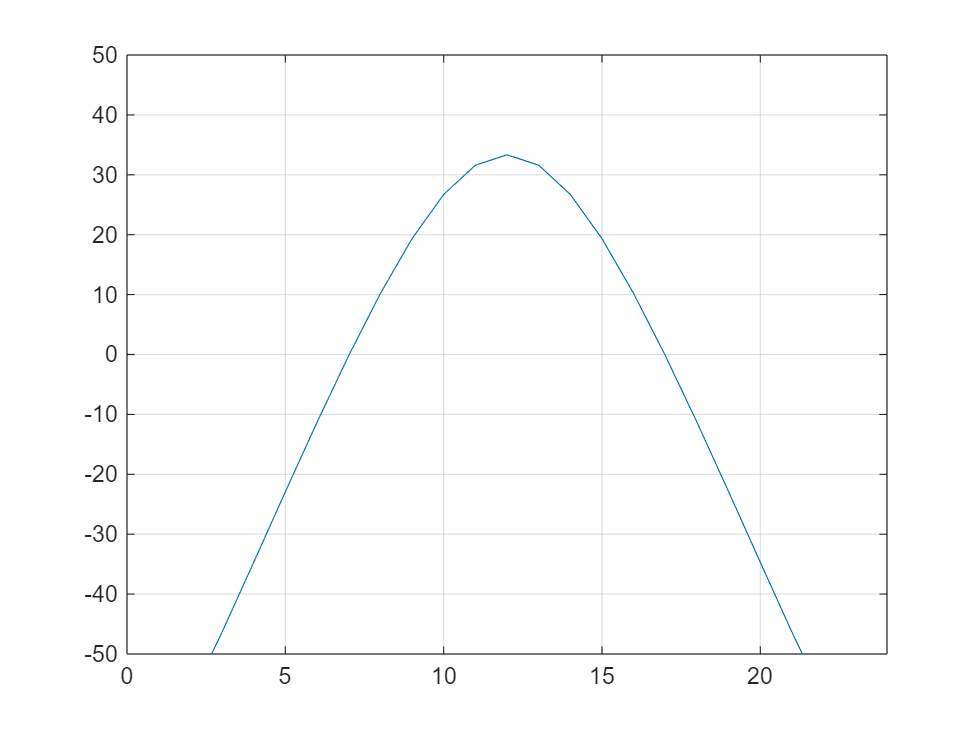


sin_a=@(t) (sind(phi)*sind(delta)+cosd(phi)*cosd(delta)*cosd(15*(t-12)));
a = asind(sin_a(t)); % Höhenwinkel alpha

cosaz=(sind(delta)-sind(a)*sind(phi))./(cosd(a)*cosd(phi));
az=real(acosd(cosaz)); % Azimut az (Winkel zur Nordrichtung)
figure;
plot(t,a)
ylim([-50 50]);
xlim([0 24]);
grid on;
hold off;

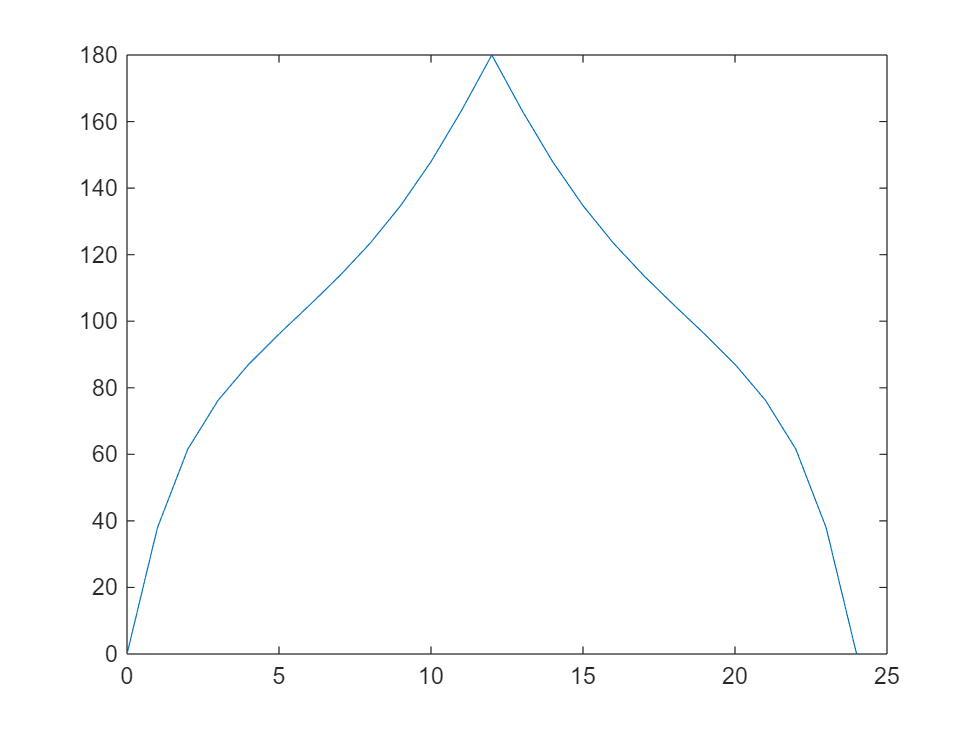


figure
plot(t,az)


max=fminbnd(@(t) (-1*(sind(phi)*sind(delta)+cosd(phi)*cosd(delta)*cosd(15*(t-12)))),0,24);
max_deg= asind(sin_a(max));
fprintf('Maximale Sonnenhöhe von %f° um %.2f Uhr \n', max_deg ,max);

Maximale Sonnenhöhe von 33.335624° um 12.00 Uhr 
